# Universal Approximator 

*© *Copyright 2022 The MathWorks, Inc


$$f:R^n \longrightarrow R^m$$


## Build a simple neural network from scratch

We concatenate different built-in layers:

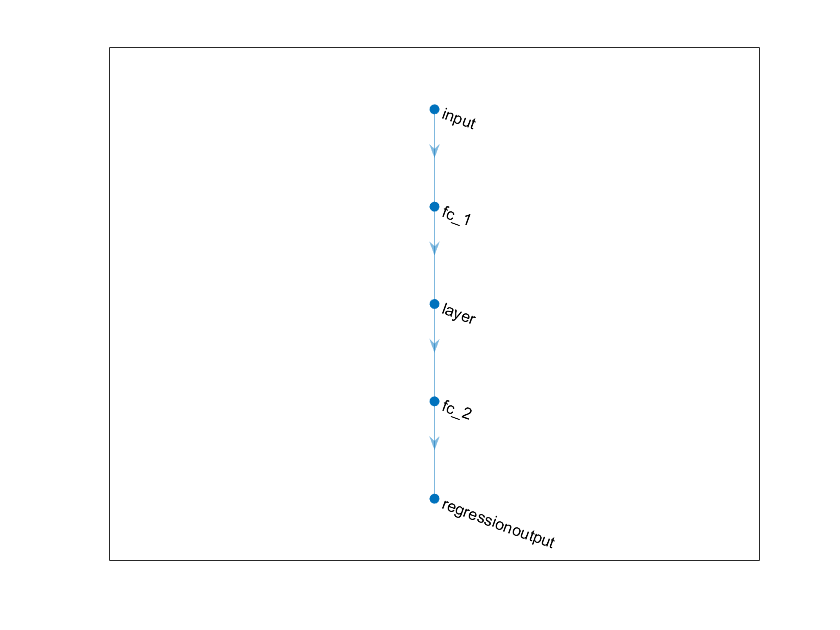

n = 10;                                        % input size
m = 20;                                        % output size 
num_neurons = 50;

layers = [featureInputLayer(n)                 % Input layer
          fullyConnectedLayer(num_neurons)     % Hidden layer
          sigmoidLayer                         % Activation
          fullyConnectedLayer(m)               % Output layer
          regressionLayer ];                   % loss layer

net = layerGraph (layers);
plot(net)

analyzeNetwork (net)